# Regression Assignment Live Script (Part 1 - Grid Partitioning)

### Initialization

clear; clc; close all

## Load, Partition and Normalize Data

data = load('airfoil_self_noise.dat');
[trnData, chkData, tstData] = partition_normalize(data);

## Define Models

#### TSK 1

tsk1_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk1_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk1_genfisOptions);
tsk1_anfisOptions = anfisOptions('InitialFIS', tsk1_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-2

tsk2_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk2_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk2_genfisOptions);
tsk2_anfisOptions = anfisOptions('InitialFIS', tsk2_initFIS, ...
                'EpochNumber', 200, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);
            

#### TSK-3

tsk3_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk3_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk3_genfisOptions);
tsk3_anfisOptions = anfisOptions('InitialFIS', tsk3_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-4

tsk4_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk4_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk4_genfisOptions);
tsk4_anfisOptions = anfisOptions('InitialFIS', tsk4_initFIS, ...
                'EpochNumber', 100, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

### Train Models

#### Train TSK 1

[tsk1_trnFIS, tsk1_trnError, ~, tsk1_valFIS, tsk1_valError]=anfis(trnData, tsk1_anfisOptions);

ANFIS info:
	Number of nodes: 92
	Number of linear parameters: 32
	Number of nonlinear parameters: 30
	Total number of parameters: 62
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 32


Start training ANFIS ...

1 	 4.22356 	 4.82069
2 	 4.19919 	 4.78434
3 	 4.17516 	 4.74844
4 	 4.1515 	 4.71304
Step size increases to 0.011000 after epoch 5.
5 	 4.12824 	 4.67821
6 	 4.1054 	 4.64399
7 	 4.08079 	 4.60712
8 	 4.05675 	 4.57111
Step size increases to 0.012100 after epoch 9.
9 	 4.03332 	 4.53603
10 	 4.01053 	 4.50194
11 	 3.98624 	 4.46565
12 	 3.9628 	 4.43068
Step size increases to 0.013310 after epoch 13.
13 	 3.94024 	 4.39709
14 	 3.9186 	 4.36493
15 	 3.89588 	 4.33123
16 	 3.87433 	 4.29931
Step size increases to 0.014641 after epoch 17.
17 	 3.85396 	 4.26919
18 	 3.83479 	 4.24086
19 	 3.81507 	 4.21175
20 	 3.79679 	 4.18473
Step size increases to 0.016105 after epoch 21.
21 	 3.77991 	 4.15975
22 	 3.76441 	 4.13673
23 	 3.7

#### Train TSK 2

[tsk2_trnFIS, tsk2_trnError, ~, tsk2_valFIS, tsk2_valError]=anfis(trnData, tsk2_anfisOptions);

ANFIS info:
	Number of nodes: 524
	Number of linear parameters: 243
	Number of nonlinear parameters: 45
	Total number of parameters: 288
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 243


Start training ANFIS ...

1 	 3.44577 	 6.45602
2 	 3.38715 	 6.98126
3 	 3.35049 	 7.6251
4 	 3.32839 	 8.13894
Step size increases to 0.011000 after epoch 5.
5 	 3.30846 	 8.4544
6 	 3.28745 	 8.61129
7 	 3.26329 	 8.6587
8 	 3.23856 	 8.60514
Step size increases to 0.012100 after epoch 9.
9 	 3.21408 	 8.49034
10 	 3.19066 	 8.36197
11 	 3.16664 	 8.23344
12 	 3.14412 	 8.08378
Step size increases to 0.013310 after epoch 13.
13 	 3.12234 	 7.84841
14 	 3.10115 	 7.52446
15 	 3.07815 	 7.06993
16 	 3.05575 	 6.54279
Step size increases to 0.014641 after epoch 17.
17 	 3.034 	 6.00904
18 	 3.01401 	 5.47195
19 	 2.99387 	 5.03498
20 	 2.97958 	 4.61477
Step size increases to 0.016105 after epoch 21.
21 	 2.96944 	 4.50412
22 	 2.96638 	 4.39892
23 	 

#### Train TSK 3

[tsk3_trnFIS, tsk3_trnError, ~, tsk3_valFIS, tsk3_valError]=anfis(trnData, tsk3_anfisOptions);

ANFIS info:
	Number of nodes: 92
	Number of linear parameters: 192
	Number of nonlinear parameters: 30
	Total number of parameters: 222
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 32


Start training ANFIS ...

1 	 2.9308 	 4.06846
2 	 2.91656 	 4.04791
3 	 2.90246 	 4.02644
4 	 2.88851 	 4.00399
Step size increases to 0.011000 after epoch 5.
5 	 2.8747 	 3.98054
6 	 2.86103 	 3.95613
7 	 2.84615 	 3.92821
8 	 2.83143 	 3.89929
Step size increases to 0.012100 after epoch 9.
9 	 2.81685 	 3.86949
10 	 2.80241 	 3.83894
11 	 2.78665 	 3.80463
12 	 2.77098 	 3.76975
Step size increases to 0.013310 after epoch 13.
13 	 2.75532 	 3.73444
14 	 2.73958 	 3.69875
15 	 2.72202 	 3.65905
16 	 2.70393 	 3.61872
Step size increases to 0.014641 after epoch 17.
17 	 2.68499 	 3.57737
18 	 2.66474 	 3.53435
19 	 2.6403 	 3.48406
20 	 2.61274 	 3.42967
Step size increases to 0.016105 after epoch 21.
21 	 2.58101 	 3.37106
22 	 2.54387 	 3.31097
23 	 

#### Train TSK 4

[tsk4_trnFIS, tsk4_trnError, ~, tsk4_valFIS, tsk4_valError]=anfis(trnData, tsk4_anfisOptions);

ANFIS info:
	Number of nodes: 524
	Number of linear parameters: 1458
	Number of nonlinear parameters: 45
	Total number of parameters: 1503
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 243



Start training ANFIS ...

1 	 2.34481 	 12.0046
2 	 2.3227 	 12.252
3 	 2.30017 	 12.5228
4 	 2.27712 	 12.8423
Step size increases to 0.011000 after epoch 5.
5 	 2.25335 	 13.2223
6 	 2.22858 	 13.6587
7 	 2.19974 	 14.1754
8 	 2.16874 	 14.678
Step size increases to 0.012100 after epoch 9.
9 	 2.1351 	 15.0916
10 	 2.09838 	 15.3385
11 	 2.05401 	 15.35
12 	 2.00505 	 15.0634
Step size increases to 0.013310 after epoch 13.
13 	 1.95117 	 14.5039
14 	 1.89227 	 13.7269
15 	 1.82206 	 12.6933
16 	 1.74702 	 11.5461
Step size increases to 0.014641 after epoch 17.
17 	 1.66835 	 10.3624
18 	 1.58766 	 9.21648
19 	 1.49982 	 8.06474
20 	 1.41873 	 7.05418
Step size increases to 0.016105 after epoch 21.
21 	 1.35195 	 6.17278
22 	 1.3049 	 5.39801
23 	 1.27341 	 4.71983
24 	 1.25602 	 4.68435
Step size increases to 0.017716 after epoch 25.
25 	 1.22892 	 4.22895
26 	 1.21159 	 4.18416
27 	 1.18179 	 3.68673
28 	 1.17037 	 3.78847
Step size increases to 0.019487 after epoch 29.
29 	 1.14366

## Benchmarking and Graphing

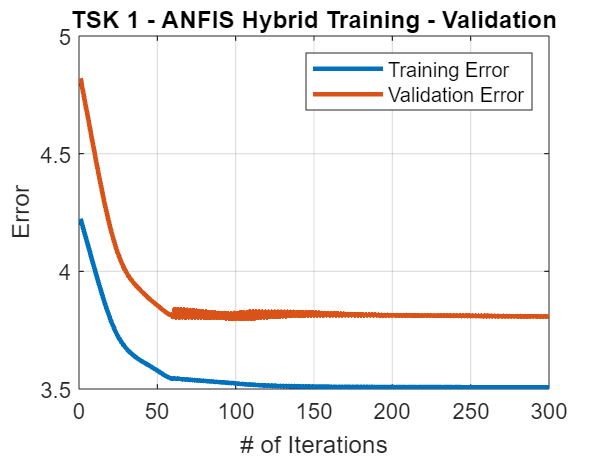

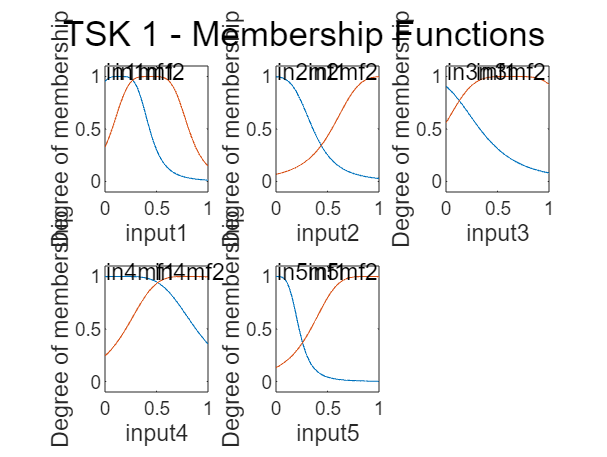

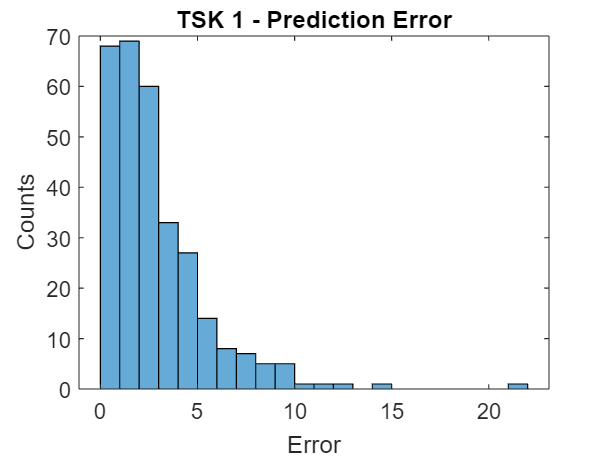

performanceStats = zeros(4,4);

%TSK-1
[RMSE, R2, NMSE, NDEI] = stats_graphs(1, tsk1_valFIS, chkData, tstData, tsk1_trnError, tsk1_valError, 1);

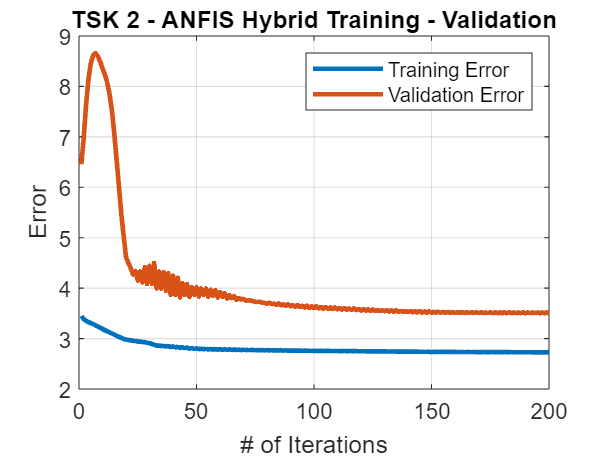

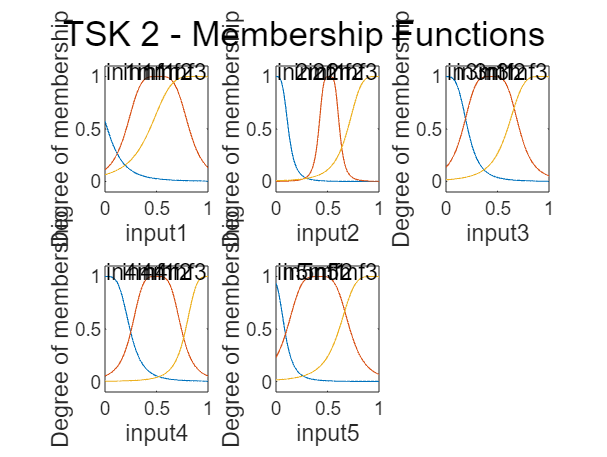

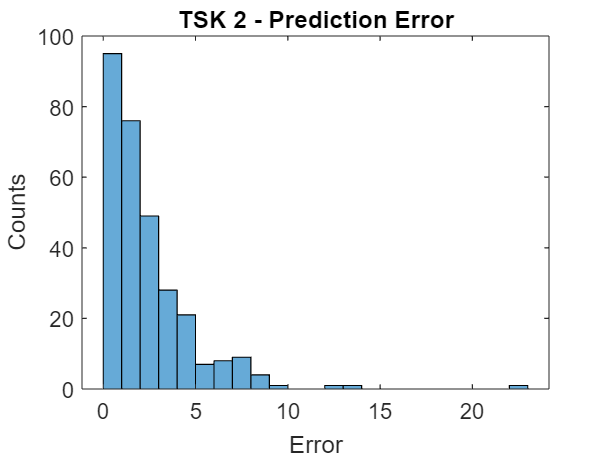

performanceStats(1,:) = [RMSE, R2, NMSE, NDEI];

%TSK-2
[RMSE, R2, NMSE, NDEI] = stats_graphs(2, tsk2_valFIS, chkData, tstData, tsk2_trnError, tsk2_valError, 1);

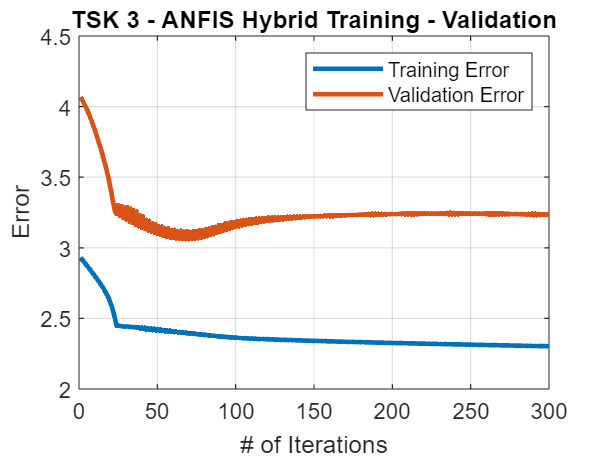

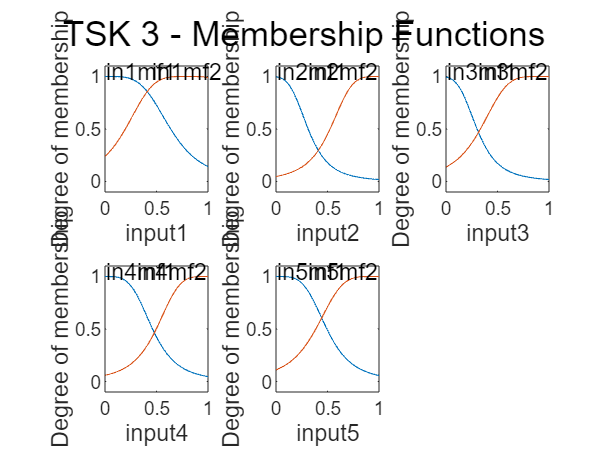

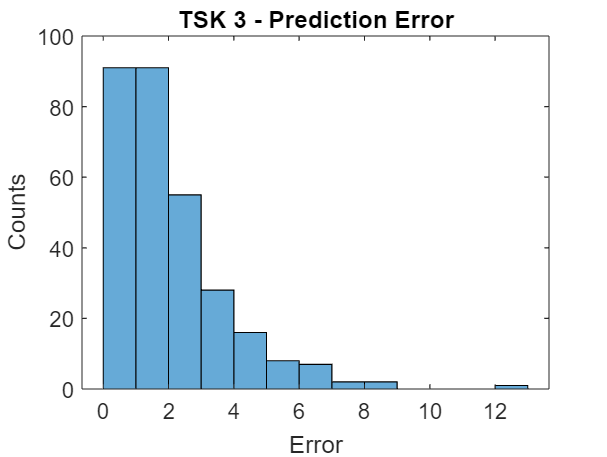

performanceStats(2,:) = [RMSE, R2, NMSE, NDEI];

%TSK-3
[RMSE, R2, NMSE, NDEI] = stats_graphs(3, tsk3_valFIS, chkData, tstData, tsk3_trnError, tsk3_valError, 1);

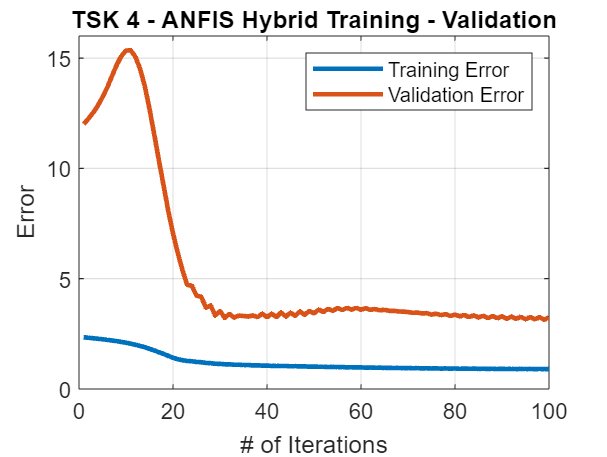

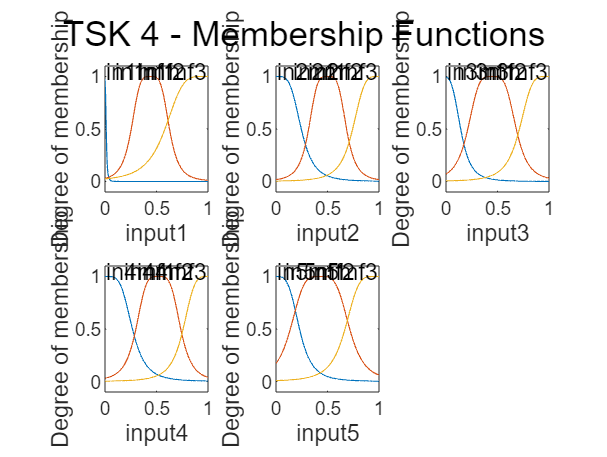

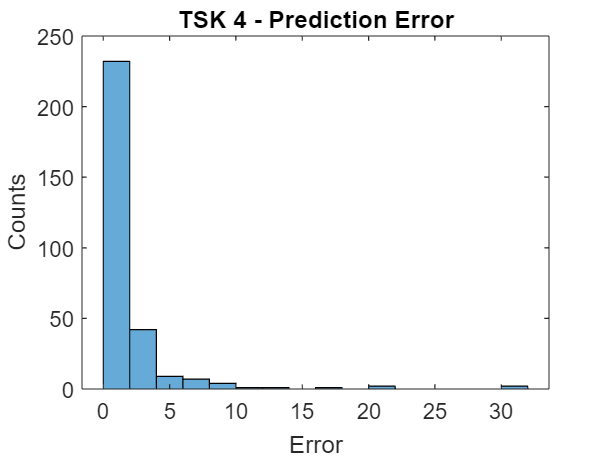

performanceStats(3,:) = [RMSE, R2, NMSE, NDEI];

%TSK-4
[RMSE, R2, NMSE, NDEI] = stats_graphs(4, tsk4_valFIS, chkData, tstData, tsk4_trnError, tsk4_valError, 1);

performanceStats(4,:) = [RMSE, R2, NMSE, NDEI];

%% Form Results Table
colNames = {'RMSE','R2','NMSE','NDEI'};
rowNames = {'TSK-1','TSK-2','TSK-3','TSK-4'};
performanceStats = array2table(performanceStats,'VariableNames',colNames,'RowNames',rowNames);